dist = ((18:2:46) - 9) * 2.54

dist =    22.8600   27.9400   33.0200   38.1000   43.1800   48.2600   53.3400   58.4200   63.5000   68.5800   73.6600   78.7400   83.8200   88.9000   93.9800


volts = [2.1603 1.9062 1.6520 1.4272 1.3245 1.1535 1.0802 0.9824 0.9091 0.8504 0.7918 0.7576 0.7234 0.7038 0.6647]

volts =     2.1603    1.9062    1.6520    1.4272    1.3245    1.1535    1.0802    0.9824    0.9091    0.8504    0.7918    0.7576    0.7234    0.7038    0.6647


copy = transpose(volts);
plot(volts, dist, "-o")
ylabel("Centimeters from sensor")
xlabel("Voltage reading (V)")
hold on;

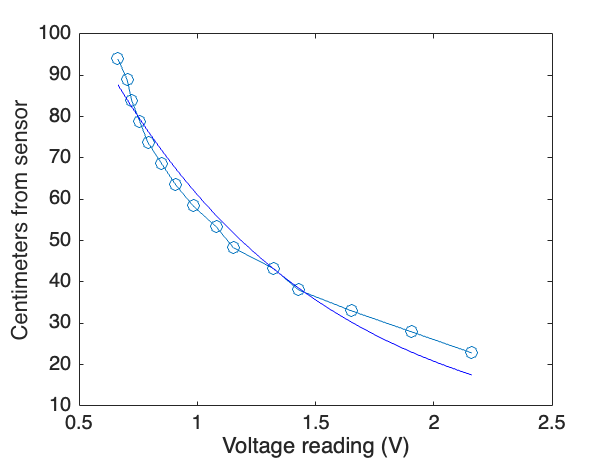

% Define the model function
modelfun = @(b, x) b(1) * exp(-b(2) * x);

% Create the initial guess for model parameters
beta0 = [50, 0.5];  % You can adjust these initial values as needed

% Fit the model to your data
mdl = fitnlm(volts, dist, modelfun, beta0);

% Extract the coefficients from the model
coefficients = mdl.Coefficients.Estimate;

% Define a range of x values for plotting
x_range = linspace(min(volts), max(volts), 100);

% Calculate the corresponding y values using the extracted coefficients
y_fit = coefficients(1) * exp(-coefficients(2)* x_range);

% Plot the data and the fitted curve
plot(x_range, y_fit, 'b');
hold off;